function r = crosscor(x, y, l)
    M = length(x);
    if length(y) ~= M
        error('Input signals x and y must have the same length.');
    end

    if l >= 0
        r = sum(x(1:M - l) .* y(1 + l:M)) / M;
    else
        l = abs(l);
        r = sum(x(1 + l:M) .* y(1:M - l)) / M;
    end
end

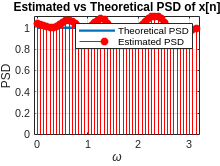

%% Assignment 5b
% Parameters
sigma_x2 = 1;
M = 1000;
L = 11;
lags = -(L-1):(L-1);
N_fft = 100;

% Generate white noise signal x[n]
x = sqrt(sigma_x2) * randn(1, M);

% Estimate autocorrelation of x[n]
r_x_hat = zeros(1, length(lags));
for idx = 1:length(lags)
    l = lags(idx);
    r_x_hat(idx) = crosscor(x, x, l);
end

% Prepare autocorrelation sequence for FFT
R_x_hat = [r_x_hat(L:end), zeros(1, N_fft - 2*L + 2), r_x_hat(L-1:-1:1)];

% Compute estimated PSD
P_x_hat = real(fft(R_x_hat));
omega = linspace(0, pi, N_fft/2 + 1);
P_x_hat = P_x_hat(1:length(omega));  % Retain positive frequencies

% Theoretical PSD
P_x_theoretical = sigma_x2 * ones(size(omega));

% Plot
figure;
plot(omega, P_x_theoretical, 'LineWidth', 2);
hold on;
stem(omega, P_x_hat, 'r', 'filled');
xlabel('\omega');
ylabel('PSD');
title('Estimated vs Theoretical PSD of x[n]');
legend('Theoretical PSD', 'Estimated PSD');
grid on;

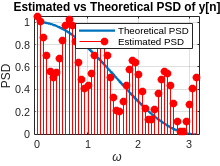

%% Assignment 5c
% Compute y[n]
x_shifted = [0, x(1:end-1)];  % x[n-1] with zero padding
y = 0.5 * (x + x_shifted);

% Estimate autocorrelation of y[n]
r_y_hat = zeros(1, length(lags));
for idx = 1:length(lags)
    l = lags(idx);
    r_y_hat(idx) = crosscor(y, y, l);
end

% Prepare autocorrelation sequence for FFT
R_y_hat = [r_y_hat(L:end), zeros(1, N_fft - 2*L + 2), r_y_hat(L-1:-1:1)];

% Compute estimated PSD
P_y_hat = real(fft(R_y_hat));
P_y_hat = P_y_hat(1:length(omega));

% Theoretical PSD
P_y_theoretical = (sigma_x2 / 2) * (1 + cos(omega));

% Plot
figure;
plot(omega, P_y_theoretical, 'LineWidth', 2);
hold on;
stem(omega, P_y_hat, 'r', 'filled');
xlabel('\omega');
ylabel('PSD');
title('Estimated vs Theoretical PSD of y[n]');
legend('Theoretical PSD', 'Estimated PSD');
grid on;

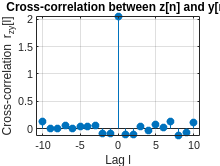

%% Assignment 6b
% Parameters
M = 1000;
tau = 5;
variance_x = 1;
variance_z = 2;

% Generate x[n] of length M + tau
x = sqrt(variance_x) * randn(1, M + tau);

% Generate z[n] of length M + tau
z = sqrt(variance_z) * randn(1, M + tau);

% Initialize y[n]
y = z;

% Compute y[n] for n = tau+1 to M+tau
y((tau + 1):(M + tau)) = y((tau + 1):(M + tau)) + x(1:M);

% Initialize variables
lags = -10:10;
r_zy = zeros(1, length(lags));

% Compute cross-correlation
for idx = 1:length(lags)
    l = lags(idx);
    r_zy(idx) = crosscor(z, y, l);
end

% Plot cross-correlation
figure;
stem(lags, r_zy, 'filled');
xlabel('Lag l');
ylabel('Cross-correlation r_{zy}[l]');
title('Cross-correlation between z[n] and y[n]');
grid on;

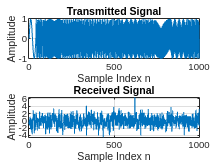

%% Assignment 6c
load('radar-5.mat');
% Plot transmitted signal
figure;
subplot(2,1,1);
plot(trans);
xlabel('Sample Index n');
ylabel('Amplitude');
title('Transmitted Signal');
grid on;

% Plot received signal
subplot(2,1,2);
plot(received);
xlabel('Sample Index n');
ylabel('Amplitude');
title('Received Signal');
grid on;

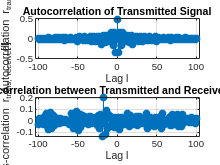

%% Assignment 6D
% Lags from -100 to 100
lags = -100:100;
r_trans = zeros(1, length(lags));

% Compute autocorrelation
for idx = 1:length(lags)
    l = lags(idx);
    r_trans(idx) = crosscor(trans, trans, l);
end

r_cross = zeros(1, length(lags));

% Compute cross-correlation
for idx = 1:length(lags)
    l = lags(idx);
    r_cross(idx) = crosscor(trans, received, l);
end

% Plot autocorrelation
figure;
subplot(2,1,1);
stem(lags, r_trans, 'filled');
xlabel('Lag l');
ylabel('Autocorrelation r_{trans}[l]');
title('Autocorrelation of Transmitted Signal');
grid on;

% Plot cross-correlation
subplot(2,1,2);
stem(lags, r_cross, 'filled');
xlabel('Lag l');
ylabel('Cross-correlation r_{trans, receive}[l]');
title('Cross-correlation between Transmitted and Received Signals');
grid on;